# Calcualtion of Inter Hamming Distance for all devices

Forthis test, we compare all combinations of the resposne of the same device type and compute the al HD metrics for each design. We then generate plots of  Hamming Distance combining all resulting HDs.

## Read data

First extract the data from the H5 file. 

clear all;
folder = 'G:\My Drive\PRL Group\04 Projects\2 Juan\1 OPUF ANT2 CHIP02\with AuNP\';
files{1} = 'AllDevices_Au1_Chips02_02_TM_user01_1705.smp';
files{2} = 'AllDevices_Au1_Chips02_02_TM_user02_1705.smp';

%Data is tagged using var(1) as the device index and var(2) as the port
%index. We compare only the drop ports in the design 3 type of devices.
dev_ind   = 13:24; 
dev_port = ones(1,length(dev_ind)); dev_port(9:12) = 2;

file_ind = 1;
for file = files
    filename = strcat(folder,file{1});
    struct = h52struct(filename);
    meas = struct.project.measurements; 
    device=[];
    for i = 1:length(dev_ind)
        idx = findinproject(dev_ind(i),dev_port(i),meas);
        m = meas(idx).spectra;
        device(:,i) = m(:,2);
        lambda = m(:,1);
    end
    dataset{file_ind} = device;
    file_ind = file_ind+1;
end

We now compute  the HD metrics for each file, the shifted datasets are computed inside of the function MultiHD

L=0.10;
results_dev1 = multi_HD(lambda, dataset{1}(:,1:4 ), L);
results_dev2 = multi_HD(lambda, dataset{1}(:,5:8 ), L);
results_dev3 = multi_HD(lambda, dataset{1}(:,[9 11 12]), L);

## **Now the plots**

We will use 'x' to mark average raw devices and 'o' to mark the responses shifted in spectrum.  

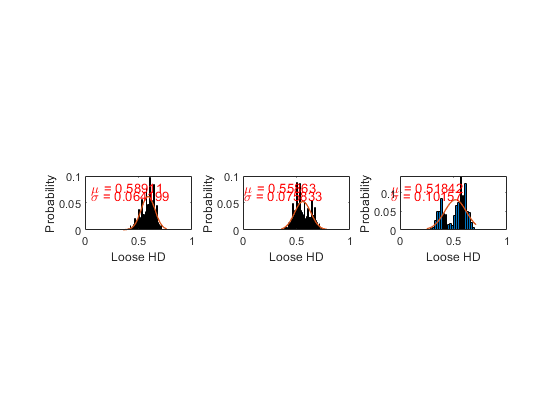

figure(1), clf, hold off;
subplot(1,3,1), [xd,pd] = plotHD(results_dev1.HDData{3}(:),'Loose HD');
subplot(1,3,2), [xd,pd] = plotHD(results_dev2.HDData{3}(:),'Loose HD');
subplot(1,3,3), [xd,pd] = plotHD(results_dev3.HDData{3}(:),'Loose HD');


avg(1,:) = mean(results_dev1.mean{1});
avg(2,:) = mean(results_dev2.mean{1});
avg(3,:) = mean(results_dev3.mean{1}); %(results_dev3.mean{1});%

sigma(1,:) = mean(results_dev1.mean{1});
sigma(2,:) = mean(results_dev2.mean{1});
sigma(3,:) = mean(results_dev3.mean{1});
%exportgraphics(gcf,'test.png','Resolution',1200,'BackgroundColor','#CCCCCC')